clc; clear all; clf;

# Avance 2: Entrenamiento, adecuacion y evaluacion de modelos

Para este avance se tomaran los diferentes datasets obtenidos en el avance 1 y se procedera a buscar el mejor /mejores modelos de clasificacion para predecir la posibilidad de intento de suicidio recurrente.

En un primer momento se probaran diferentes modelos , haciendo uso de la herramienta   "Classification Learner" de Matlab, debido a  su facilidad y rapidez para probar multiples modelos simultaneamente. Se tomaran los pares dataset-modelo que mejores resultados den (preferiblemente por encima de 70% de acierto) para seguirlos trabajando, en cuanto a seleccion de parametros y ajuste de hiperparametros.

Para la seleccion de parametros y ajuste de hiperparametros en donde sea posible se usaran herramientas interactivas o automaticas que provee MAtlab. 

Como metodos de validacion y calificacion de los modelos se prentenden usar los dados a continuacion (To Do: añadir breve descripcion de cada uno)

- Score

- Matriz de confusion

- ROC curve

Debido al problema a resolver, al momento de realizar predicciones se generaran dos. Un deterrministica y otra probabilistica.

**Descripcion de los data set de entrada.**

En el avance 1 se obtuvieron 4 datasets despues del proceso de limpieza, los cuales se describiran a continuacion:

- cds_imputed : dataset con 33 carateristicas y 4146 registros

- cds : dataset con 28 caracteristicas 4146 registros, 

- cds_few : 33 caracteristicas y 655 registros

- cds_fem_minus_alcohol:  32 caracteristicas 1690 registros.

%cds = readtable('cds.csv'); size_cds = size(cds)
cds_imputed = readtable('cds_imputed.csv'); size_imputed = size(cds_imputed)

size_imputed =         4146          34


cds_imputed = movevars(cds_imputed,'inten_prev','after','tipo_ss_S');
%cds_few = readtable('cds_few.csv'); size_few = size (cds_few)
%cds_few_minus_alcohol = readtable('cds_few_minus_alcohol.csv'); size_few_minus_alcohol = size (cds_few_minus_alcohol)

Con estos dataset se procede realizar un enntrenamiento exploratorio de modelos , para  continuar con los mas prometedores. Sin embargo, es necesarion definir el concepto de "mas prometedor". En este primer momeno se tendra en cuanta la exactitud del modelos

Es de utilidad tener en cuenta que para lo expuesto a continuacion fue usada validacion cruzaada con "k-folds"( k=5) ,y el valor de precision presentado es correspondiente a esto. 

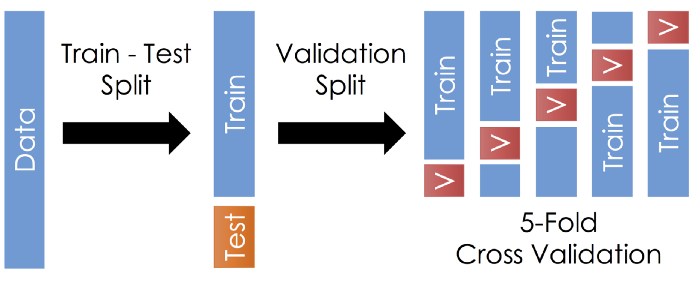

Resultados cds

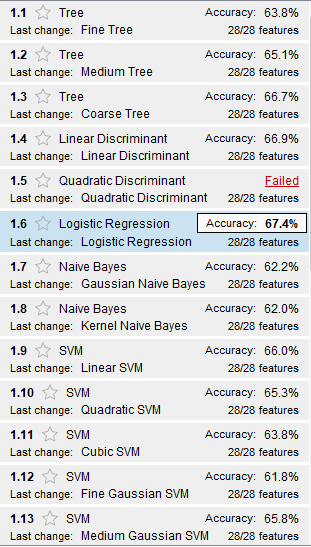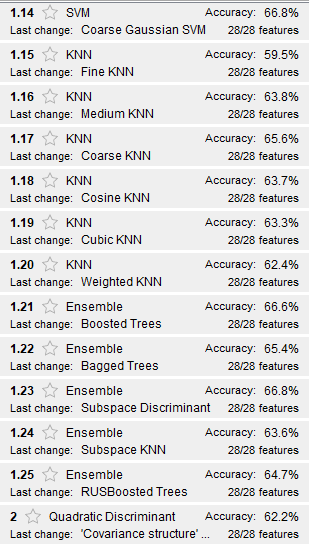

Resultados cds_imputed

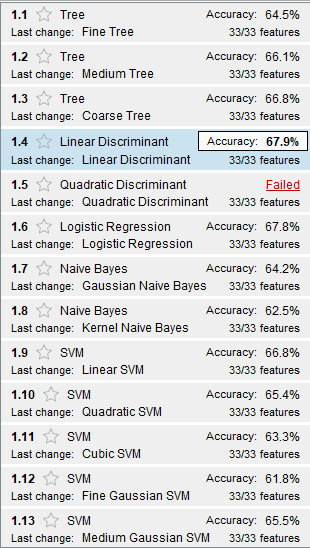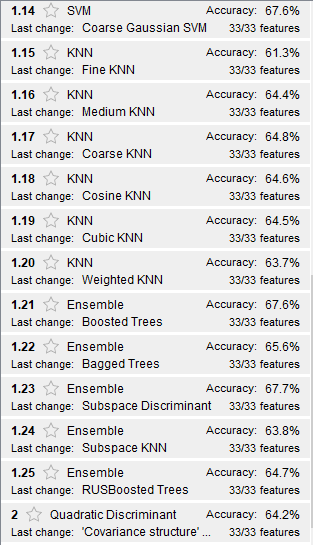

Resultados cds_few

Para este dataset algunos modelos se hicieron individualmente, porque presentaban problemas con las caracteristicas 'antec_tran', 'tipo_ss_I', 'suici_fm_a' y 'tipo_SS_P ya que la mayoria o casi todos sus valores son iguales o no presentan variacion con respecto a una de las clases por hallar, por lo que no aportan informacion 

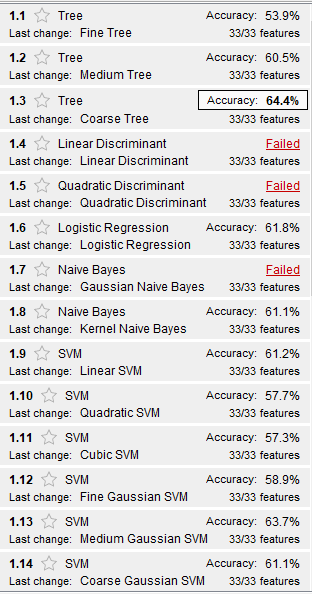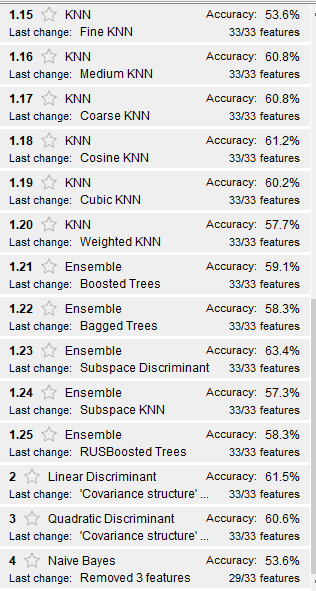

Resultados cds_few_minus_alcohol

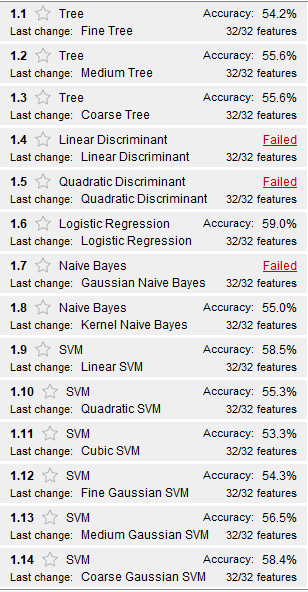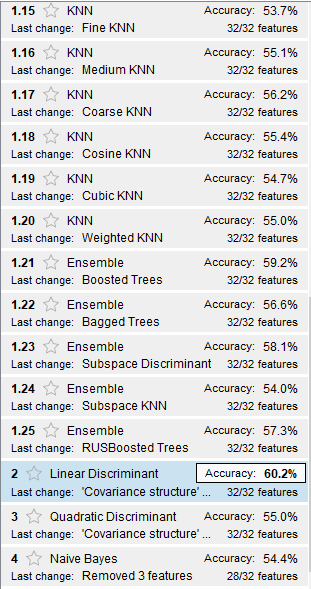

Por motivos exploratorios se realizaron pruebas aplicandole PCA a los datos, pero los resultadon en general fueron inferiores(en terminos de precision) a los obtenidos sin esta transformacion. ***(¿Uno si deberia hacer PCA en datos categoricos?) ***

Como se puede notar, ningun par dataset-modelo obtuvo una precision mayore al 70% tal y como se habia definido inicialmente para su aceptacion. Por este motivo se tomara aquel dataset que produjo el modelo con la mayor precision(cds_imputed) y los mejores modelos obtenidos a partir de este. 

Coarse Tree, Linear discriminant, Logistic regresion , SVM coarse  emse

**Feature selection**

Bucando reducir la dimensionalidad y explorar direferente opciones se pretende realizar un proceso de seleccion de caracteriscas. Esto se hara filtrando aquellas caracteristicas menos importantes para la respuesta 'inten_prev' mediante el algoritmo MRMR(Minimum Redundancy Maximun Relevance), del cual se puede obtener el "ranking" de importancia de los predictores teniendo en cuentas la respuesta.

Se entrenaran 2 modelos, uno con todas las caracteristicas y adicionalmente otro con el conjunto de las 7 mas importantes

idx = fscmrmr(cds_imputed,'inten_prev');
most_signif_features = cds_imputed.Properties.VariableNames(idx(1:7)).'

most_signif_features = 7×1 cell array
    {'antec_tran'}
    {'hist_famil'}
    {'muerte_fam'}
    {'antec_v_a' }
    {'prob_consu'}
    {'plan_suici'}
    {'gp_psiquia'}


less_signif_features =cds_imputed.Properties.VariableNames(idx(end-4:end)).'

less_signif_features = 5×1 cell array
    {'escolarid' }
    {'esco_educ' }
    {'tipo_ss_C' }
    {'trab_socia'}
    {'sexo_'     }


**Optimizacion de hiperparametros**

Se presentara el proceso para cada uno de los modelos reaizados 

Arboles de decision:

**Presentacion de resultados usando el data set completo y el reducido despues de la seelccion de caracteristicas**

 caso se tendran en cuenta varias cosas:

- La precision del modelo, mientras mayor mejor, sin llegar a un caso de sobreajuste.

- El numero de parametros, en general es de interes obtener modelos que con un bajo numero de parametros sean capaces de cumplir con su objetivo a cabalidad, esto debido a que en un caso real es mas dificil y costoso, en terminop de dinero y timepo obtener mas informacion.En este caso no le daremos mayor importancia a unos parametrso sobre otros, nos concentraremos principalmente en el numero de ellos.

- Un ultimo factor que se tendra en cuenta para preferir un modelo sobre otro es la presdisposicion de falsos positvios hacia cierta clase particular, i.e.  en este contexto no seria nada bueno identificar erroneamente a aquellas personas con tendencia repetitiva al intento de suicidio, mientras que identificar erroneamente a aquellos que en realidad no seria mas aceptable.Esto se tendra en cuenta al observar matrices de confusion despues de realizar la optimizacion de hiperparametros.

When you open the plot, the rows show the true class, and the columns show the predicted class. If you are using holdout or cross-validation, then the confusion matrix is calculated using the predictions on the held-out observations. The diagonal cells show where the true class and predicted class match. If these diagonal cells are blue, the classifier has classified observations of this true class are classified correctly.

**Conclusiones**

**Select Features to Include**

In Classification Learner, you can specify different features (or predictors) to include in the model. See if you can improve models by removing features with low predictive power. If data collection is expensive or difficult, you might prefer a model that performs satisfactorily without some predictors.

dando prioridad a los sugeridos por el profesor: Regresion logistica, SVM, Arboles de decision, Redes neuronales, LMP, Random Fores

Intent_prev{1 = SI; 2 = NO}

Refs:

[https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation.html](https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation.html)

[https://www.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html](https://www.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html)

[https://www.mathworks.com/help/stats/assess-classifier-performance.html](https://www.mathworks.com/help/stats/assess-classifier-performance.html)

[https://towardsdatascience.com/intuitive-hyperparameter-optimization-grid-search-random-search-and-bayesian-search-2102dbfaf5b](https://towardsdatascience.com/intuitive-hyperparameter-optimization-grid-search-random-search-and-bayesian-search-2102dbfaf5b)

[https://towardsdatascience.com/automated-machine-learning-hyperparameter-tuning-in-python-dfda59b72f8a](https://towardsdatascience.com/automated-machine-learning-hyperparameter-tuning-in-python-dfda59b72f8a)

[https://towardsdatascience.com/workflow-of-a-machine-learning-project-ec1dba419b94](https://towardsdatascience.com/workflow-of-a-machine-learning-project-ec1dba419b94)

[https://www.mathworks.com/help/stats/feature-selection.html](https://www.mathworks.com/help/stats/feature-selection.html)

%Feature selection tests
%X = table2array([cds(:,1:2), cds(:, 4:end)])
%y = table2array(cds(:,3))
%ncaMdl = fscnca(X,y,'FitMethod','exact','Verbose',1,'Solver','lbfgs');
%Model1 = stepwiselm(X,Y,'constant','ResponseVar','ResResistant')
%Model2 = stepwiselm(X,Y,'linear','ResponseVar','ResResistant')


% figure
% semilogx(ncaMdl.FeatureWeights,'ro')
% xlabel('Feature index')
% ylabel('Feature weight')   
% grid on

% cds_new = movevars(cds,'inten_prev','after','tipo_ss_S');

% [idx,scores] = fscmrmr(cds_new,"antec_tran");
% bar(scores(idx))
% xlabel('Predictor rank')
% ylabel('Predictor importance score')

% idx(1:5)
% cds_new.Properties.VariableNames()
% cds_new.Properties.VariableNames(idx(1:5))

% cds_new.Properties.VariableNames(idx(end-4:end))